**Traitement des données électromyographique sujets sains (FUNCTIONAL)**

Contexte : analyse des données des tâches motrices **fonctionelles** sur 7 muscles de l'épaule lors de différentes actions : 

- FUNCTIONAL1 : porter les mains à la bouche

- FUNCTIONAL2 : toucher le haut de la tête

- FUNCTIONAL3 : porter les mains le plus haut possible au-dessus de la tête

- FUNCTIONAL4 : porter les mains le plus haut possible le long de la colonne vertébrale

Paramètres

clc; clear all; 

% Ajout de la bibliothèque btk 
addpath(genpath('C:\Users\Francalanci Hugo\Documents\MATLAB\Stage Sainte-Justine\HUG\btk'));

% Définition sujet
subjects = {'MF01'};
%              'MF01', 'TF02', 'YL03','SC04', 'RF05', 'AP06'
%              'TD07', 'IS08', 'LC09', 'MP10', 'PK11'
%              'TF12','JM13', 'GD14', 'LD15', 'LM16','NQ17', 'JV18'
%              'EG19', 'MG20', 'LB21', 'AP22', 'SC23'
%              'TM24', 'EG25', 'RL26'

% Définition des muscles pour les côtés droit et gauche
muscles_R = {'RDELTA', 'RDELTM', 'RDELTP', 'RTRAPI', 'RTRAPM', 'RTRAPS', 'RLATD', 'RSERRA'};
muscles_L = {'LDELTA', 'LDELTM', 'LDELTP', 'LTRAPI', 'LTRAPM', 'LTRAPS', 'LLATD', 'LSERRA'};

% Définition des functionals
functional_labels = {...
    'Porter les mains à la bouche', ...
    'Toucher le haut de la tête', ...
    'Porter les mains le plus haut possible au-dessus de la tête', ...
    'Porter les mains le plus haut possible le long de la colonne vertébrale'
    };

Echelle normalisée pour tous les muscles (visualisation globale du signal)

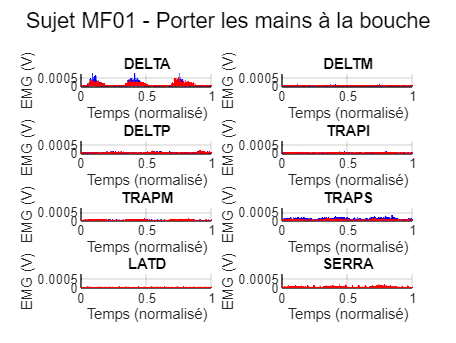

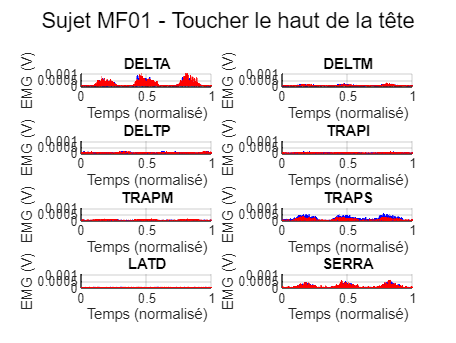

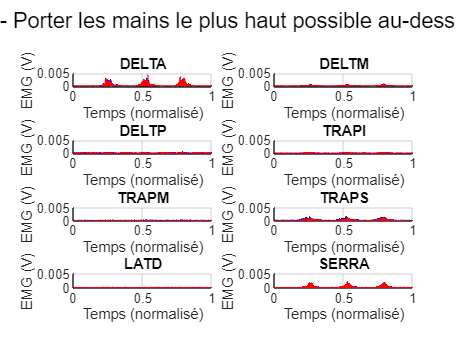

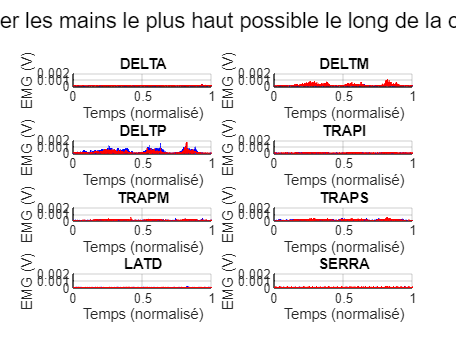

% Appel de la fonction pour obtenir les données brutes
plot_EMG_from_C3D_functional(subjects, muscles_R, muscles_L, functional_labels, 'C:\Users\Francalanci Hugo\Documents\MATLAB\Stage Sainte-Justine\HUG\Sujets');

Echelle non normalisée pour tous les muscles (visualisation plus précise du signal)

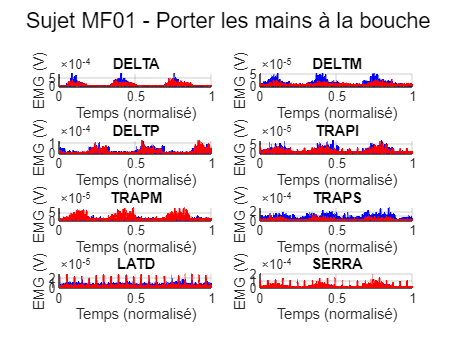

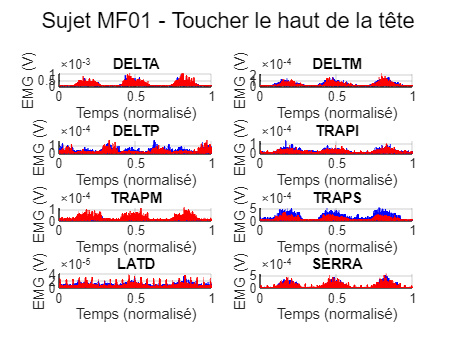

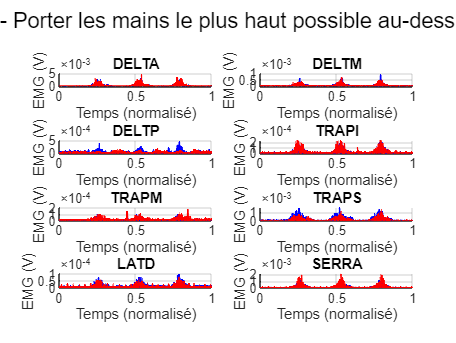

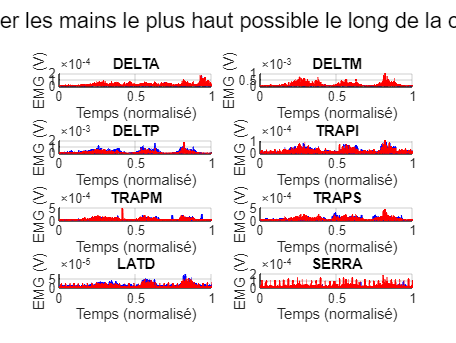

% Appel de la fonction pour obtenir les données brutes
plot_EMG_from_C3D_functional_nnorm(subjects, muscles_R, muscles_L, functional_labels, 'C:\Users\Francalanci Hugo\Documents\MATLAB\Stage Sainte-Justine\HUG\Sujets');